close all; clear all; clc;

Homework 2

Liangzhe Liu, 1663973

1) Probability to roll a snake eye is $\frac{1}{36}$, and probability to roll a seven is $\frac{6}{36}=\frac{1}{6}$. So, rolling sevens is more probable and the ratio of these two probability is $1:6$.

2) The probability of getting 2 is $\frac{1}{36}$

    The probability of getting 3 is $\frac{2}{36}$

    The probability of getting 4 is $\frac{3}{36}$

    The probability of getting 5 is $\frac{4}{36}$

    The probability of getting 6 is $\frac{5}{36}$

    The probability of getting 7 is $\frac{6}{36}$

    The probability of getting 8 is $\frac{5}{36}$

    The probability of getting 9 is $\frac{4}{36}$

    The probability of getting 10 is $\frac{3}{36}$

    The probability of getting 11 is $\frac{2}{36}$

    The probability of getting 12 is $\frac{1}{36}$

u = ones(1,6) % The probability of getting any number on a dice is equal.

u =      1     1     1     1     1     1


w = conv(u,u) % 2 dices are identical.

w =      1     2     3     4     5     6     5     4     3     2     1


p = w/36 % Divided by 36 to make the sum of the probability equals to 1.

p =     0.0278    0.0556    0.0833    0.1111    0.1389    0.1667    0.1389    0.1111    0.0833    0.0556    0.0278


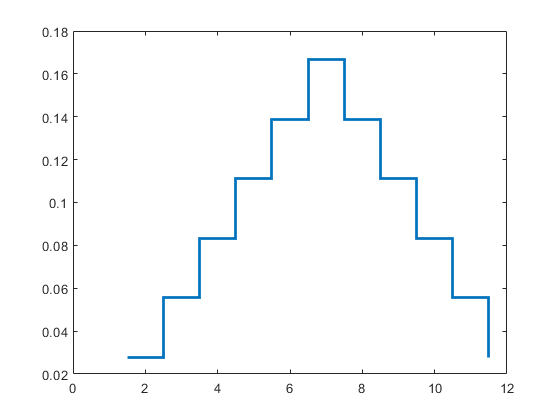

x = 2:12; % values on x axis.
stairs(x-0.5,p,"LineWidth",2)

3) 

% Make a data set that has the sum of two dices to fit the distribution
data = zeros(36,1);
counter = 1;
for i = 1:11
    for j = 0:w(i)-1
        data(counter) = x(i);
        counter = counter + 1;
    end
end
d = fitdist(data,'Poisson');
mean = mean(d)

mean = 7

variance = var(d)

variance = 7

4)

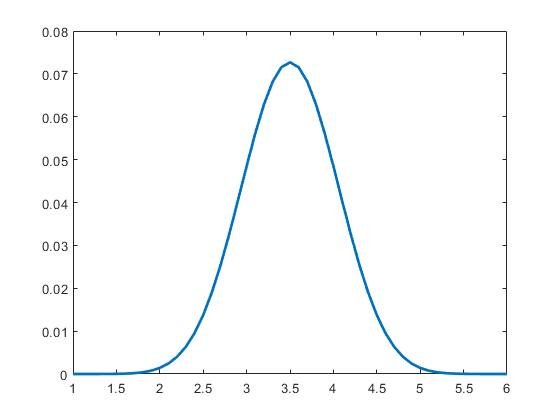

v = [1 1 1 1 1 1];
for i = 1:9
    v = conv(u,v);
end
p10 = v/6^10;
x10 = 1:0.1:6;
plot(x10,p10,"LineWidth",2)

5) 

normal1 = makedist("Normal");
normal2 = makedist("Normal","mu",5,"sigma",0.5);
